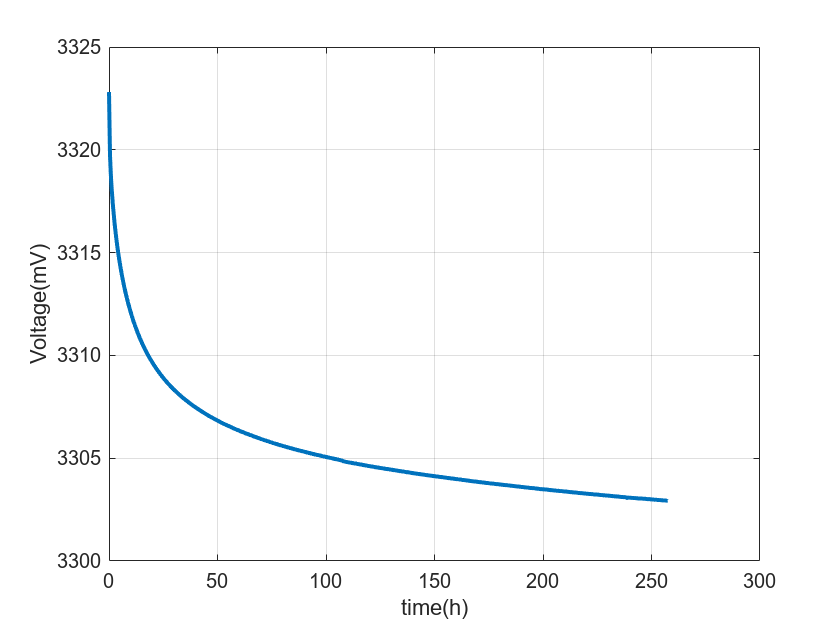

clc
clear
close all
Voltage_data=readmatrix('.\cell_1.csv');
fit_time=2;%h
fit_length=floor(fit_time*3600/30);
t_seri=Voltage_data(1:fit_length,1);
U_exp=Voltage_data(1:fit_length,2)*1000;%mV
exp_data=[t_seri(2:end),U_exp(2:end)];
figure;plot(Voltage_data(:,1)/3600,Voltage_data(:,2)*1000,LineWidth=2);
xlabel('time(h)');ylabel('Voltage(mV)');grid on;

**1.使用Relaxation-linear 模型，时间常数随时间线性变化,**$\tau =\alpha t+\beta \;$**,损失函数使用均方误差RMSE**

object_fun_1=@(x_sol)OCV_fit_object(x_sol,exp_data,"fitness",'RMSE','methode','Relaxation');
OCV_0=U_exp(end);
alph_0=20;
beta_0=25;
lb=[alph_0*1e-1,beta_0*1e-1,OCV_0-300];
ub=[alph_0*5,beta_0*1e3,OCV_0+300];
% pso solver
options_1 = optimoptions('particleswarm','SwarmSize',30,'Display','iter','HybridFcn',@fmincon);
[result1.x_sol,result1.f_val,result1.exitflag] = particleswarm(object_fun_1,length(ub),lb,ub,options_1);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              30          0.3168           7.346        0
    1              60          0.3168           27.72        0
    2              90          0.1226           8.396        0
    3             120          0.1226           13.88        1
    4             150          0.1226           7.527        2
    5             180          0.1226           5.636        3
    6             210          0.1226           6.844        4
    7             240         0.09779           7.427        0
    8             270         0.09779           5.645        1
    9             300         0.09779           9.738        2
   10             330         0.09779           9.587        3
   11             360         0.09779            4.19        4
   12             390         0.08392           3.126        0
   13             420         0.08392           

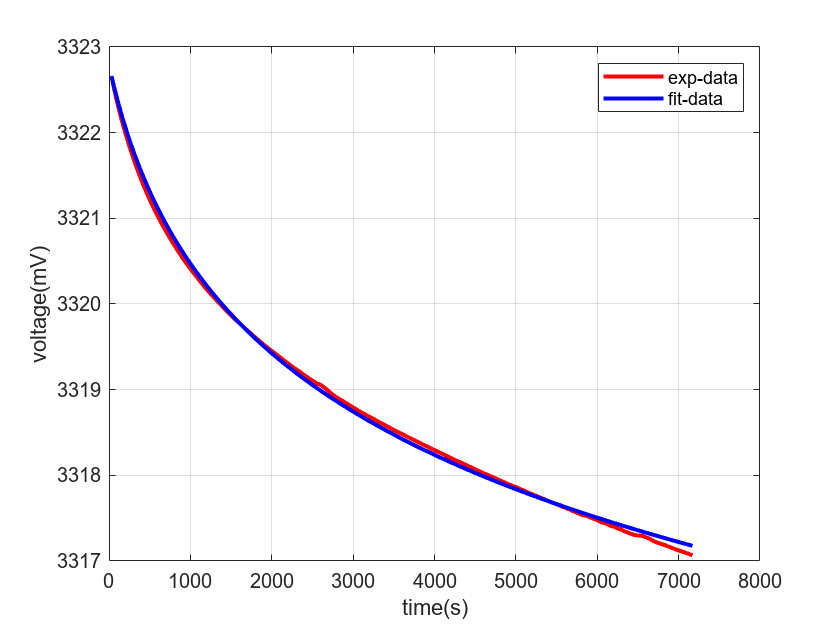

% result
[result1.RMSE,result1.Chi_2,result1.U_diff]=plot_result(result1.x_sol,exp_data,"methode",'Relaxation');

**2.使用Relaxation-nolinear 模型，时间常数随时间线性变化,**$\tau =\alpha t^{\gamma \;} +\beta \;$**,损失函数使用均方误差RMSE**

object_fun_2=@(x_sol)OCV_fit_object(x_sol,exp_data,"fitness",'RMSE','methode','Relaxation-nolinear');
OCV_0=U_exp(end);
alph_0=20;
beta_0=25;
gamma_0=1;
lb=[alph_0*1e-1,beta_0*1e-1,gamma_0*1e-4,OCV_0-300];
ub=[alph_0*5,beta_0*1e3,gamma_0*1e2,OCV_0+300];
% pso solver
options_2 = optimoptions('particleswarm','SwarmSize',30,'Display','iter','HybridFcn',@fmincon);
[result2.x_sol,result2.f_val,result2.exitflag] = particleswarm(object_fun_2,length(ub),lb,ub,options_2);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              30           4.095           4.095        0
    1              60           4.095           33.79        0
    2              90           4.095           6.813        1
    3             120           3.544           12.04        0
    4             150           3.208           32.38        0
    5             180           3.208           11.66        1
    6             210           2.421           28.21        0
    7             240          0.8225           26.36        0
    8             270          0.8225           15.93        1
    9             300          0.8225           9.695        2
   10             330          0.8141           29.87        0
   11             360          0.8141           15.06        1
   12             390          0.8141           41.94        2
   13             420          0.8141           

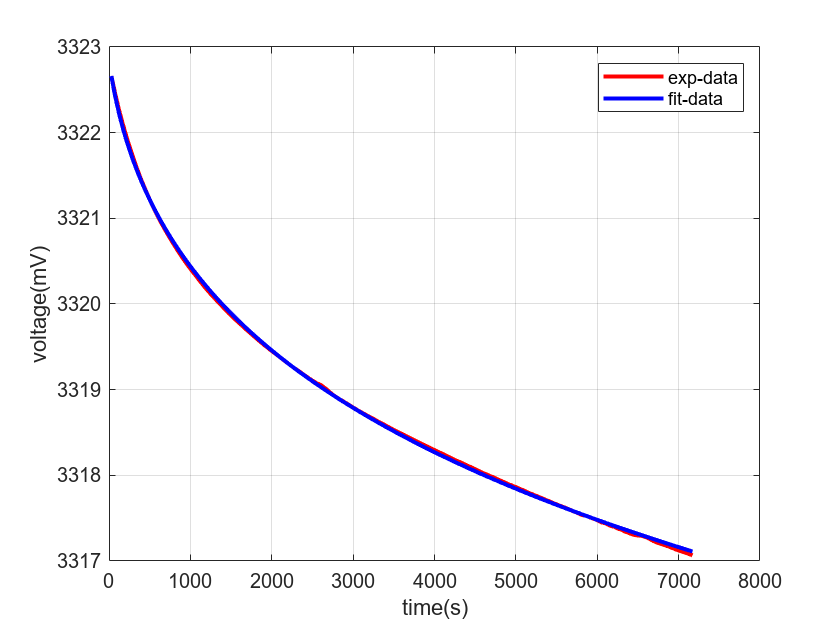

% result
[result2.RMSE,result2.Chi_2,result2.U_diff]=plot_result(result2.x_sol,exp_data,"methode",'Relaxation-nolinear');

**3.使用Nernst 模型,**$Ut=OCV-a_{3\;} \cdot t^{a_{4\;} } \ln \left(t\right)-a_{1\;} t^{a_2 }$**,损失函数使用均方误差RMSE**

object_fun_3=@(x_sol)OCV_fit_object(x_sol,exp_data,"fitness",'RMSE','methode','Nernst');
OCV_0=U_exp(end);
lb=[100,-1e4,-1e2,-1e-5,OCV_0-300];
ub=[1e5,10,10,10,OCV_0+300];
% pso solver
options_3 = optimoptions('particleswarm','SwarmSize',30,'Display','iter','HybridFcn',@fmincon);
[result3.x_sol,result3.f_val,result3.exitflag] = particleswarm(object_fun_3,length(ub),lb,ub,options_3);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              30           125.5       7.084e+37        0
    1              60           125.5       2.531e+40        0
    2              90           33.44        2.13e+41        0
    3             120           20.01       8.335e+40        0
    4             150           19.29       2.508e+40        0
    5             180           19.29       1.445e+41        1
    6             210            11.3       9.293e+40        0
    7             240            11.3       2.704e+41        1
    8             270           5.586       2.046e+41        0
    9             300           5.586        1.94e+41        1
   10             330           5.586       2.669e+38        2
   11             360           5.586       2.669e+38        3
   12             390           5.586       1.335e+41        4
   13             420           5.586       6.62

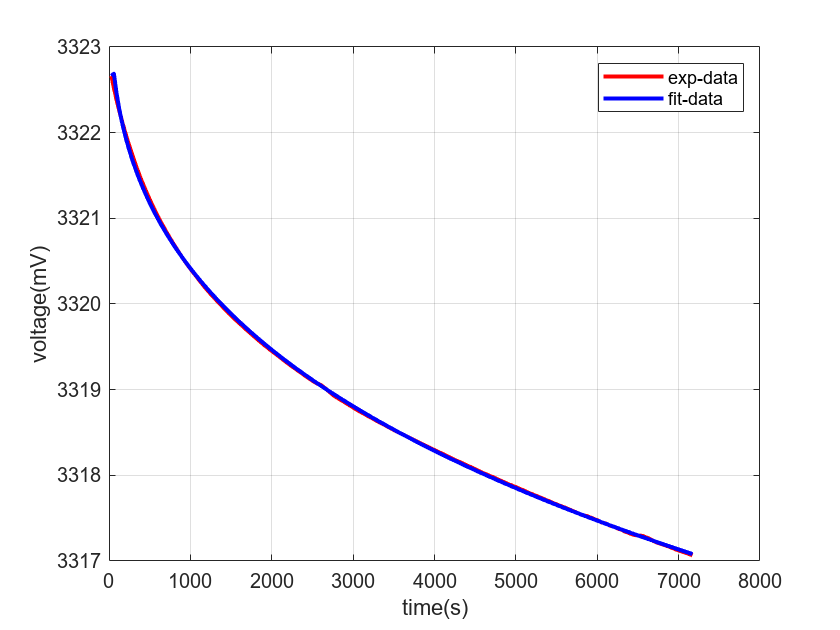

% result
[result3.RMSE,result3.Chi_2,result3.U_diff]=plot_result(result3.x_sol,exp_data,"methode",'Nernst');

**4.使用Nernst 模型，损失函数使用负拟合残差**$-\chi$

object_fun_4=@(x_sol)OCV_fit_object(x_sol,exp_data,"fitness",'Chi-2','methode','Nernst');
OCV_0=U_exp(end);
lb=[100,-1e4,-1e2,-1e-5,OCV_0-300];
ub=[1e5,10,10,10,OCV_0+300];
% pso solver
options_4 = optimoptions('particleswarm','SwarmSize',30,'Display','iter','HybridFcn',@fmincon);
[result4.x_sol,result4.f_val,result4.exitflag] = particleswarm(object_fun_4,length(ub),lb,ub,options_4);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              30       5.589e+05       5.054e+36        0
    1              60            2179       9.851e+42        0
    2              90           852.1       1.747e+44        0
    3             120           488.7       7.138e+43        0
    4             150           488.7       9.565e+43        1
    5             180           488.7       5.394e+43        2
    6             210           488.7        1.58e+44        3
    7             240           488.7       4.576e+43        4
    8             270           488.7       1.386e+44        5
    9             300           488.7       1.516e+44        6
   10             330           488.7       7.997e+43        7
   11             360           359.6       3.997e+43        0
   12             390           359.6       1.988e+43        1
   13             420           321.4       4.36

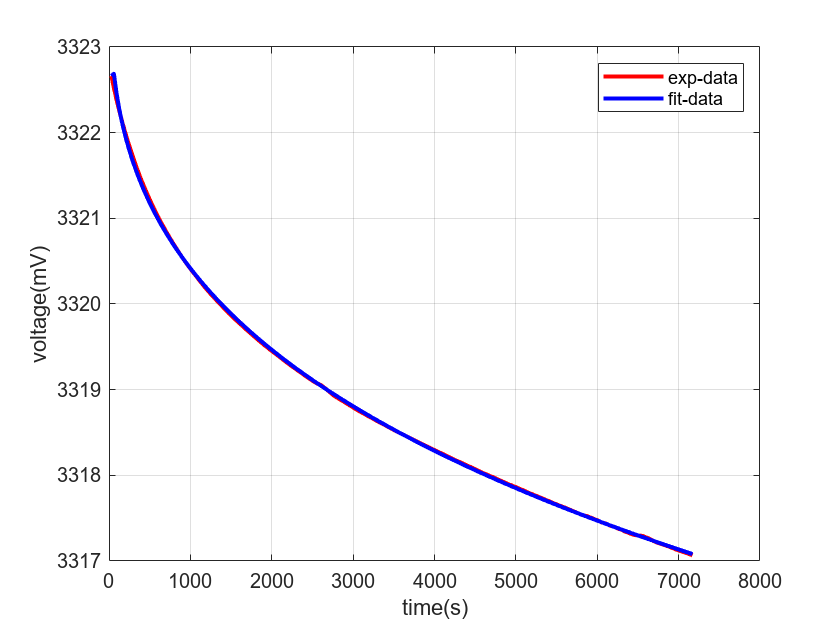

% result
[result4.RMSE,result4.Chi_2,result4.U_diff]=plot_result(result4.x_sol,exp_data,"methode",'Nernst');

**5.使用Relaxation-nolinear 模型，时间常数随时间线性变化,**$\tau =\alpha t^{\gamma \;} +\beta \;$**,损失函数使用负拟合残差**$-\chi$

object_fun_5=@(x_sol)OCV_fit_object(x_sol,exp_data,"fitness",'Chi-2','methode','Relaxation-nolinear');
OCV_0=U_exp(end);
alph_0=20;
beta_0=25;
gamma_0=1;
lb=[alph_0*1e-1,beta_0*1e-1,gamma_0*1e-4,OCV_0-300];
ub=[alph_0*10,beta_0*1e3,gamma_0*1e2,OCV_0+300];
% pso solver
options_5 = optimoptions('particleswarm','SwarmSize',30,'Display','iter','HybridFcn',@fmincon);
[result5.x_sol,result5.f_val,result5.exitflag] = particleswarm(object_fun_5,length(ub),lb,ub,options_5);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              30           206.6           206.6        0
    1              60           206.6            2372        0
    2              90           206.6           480.8        1
    3             120           206.6            1026        2
    4             150           73.22           735.3        0
    5             180           73.22            1619        1
    6             210           73.22            1063        2
    7             240          -45.17           779.8        0
    8             270          -45.17            1130        1
    9             300          -45.17           674.5        2
   10             330          -45.17            1071        3
   11             360          -45.17            1055        4
   12             390          -45.17           855.2        5
   13             420          -45.17           

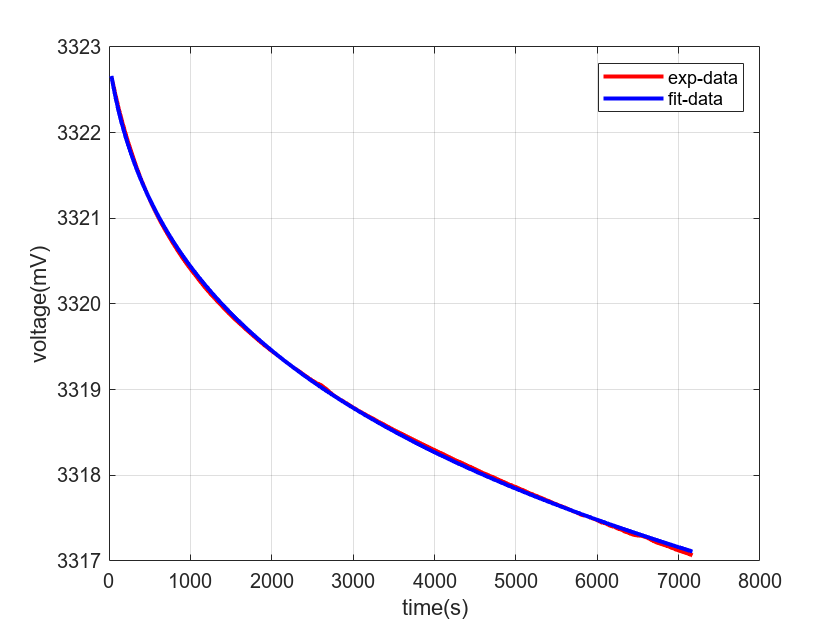

% result
[result5.RMSE,result5.Chi_2,result5.U_diff]=plot_result(result5.x_sol,exp_data,"methode",'Relaxation-nolinear');

**6.使用Relaxation-nolinear 模型，时间常数随时间线性变化,**$\tau =\alpha t^{\gamma \;} +\beta \;$**,损失函数使用负拟合残差**$-\chi$**，fmincon求解**

object_fun_6=@(x_sol)OCV_fit_object(x_sol,exp_data,"fitness",'Chi-2','methode','Relaxation-nolinear');
OCV_0=U_exp(end);
alph_0=20;
beta_0=25;
gamma_0=1;
x0=[alph_0,beta_0,gamma_0,OCV_0];
lb=[alph_0*1e-1,beta_0*1e-1,gamma_0*1e-4,OCV_0-300];
ub=[alph_0*10,beta_0*1e3,gamma_0*1e2,OCV_0+300];
% fmincon solver
options_6 = optimoptions('fmincon','Display','iter');
[result6.x_sol,result6.f_val,result6.exitflag] = fmincon(object_fun_6,x0,[],[],[],[],lb,ub,[],options_6);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.292260e+02    0.000e+00    2.082e+02
    1      12   -5.177231e+01    0.000e+00    1.034e+03    1.789e+00
    2      20   -6.277723e+01    0.000e+00    1.434e+02    9.063e-01
    3      27   -6.425598e+01    0.000e+00    7.466e+01    1.402e+00
    4      32   -6.573169e+01    0.000e+00    2.821e+02    1.999e+00
    5      37   -6.714100e+01    0.000e+00    6.325e+01    8.232e-01
    6      42   -6.749974e+01    0.000e+00    5.028e+02    4.547e+00
    7      47   -7.079144e+01    0.000e+00    2.203e+01    2.191e+00
    8      52   -7.103358e+01    0.000e+00    5.981e+02    6.311e+00
    9      57   -7.291901e+01    0.000e+00    1.434e+02    6.765e-01
   10      62   -7.409357e+01    0.000e+00    1.327e+02    4.090e+00
   11      67   -7.592445e+01    0.000e+00    1.537e+02    7.830e+00
   12      73   -7.773385e+01    0.000e+00    4

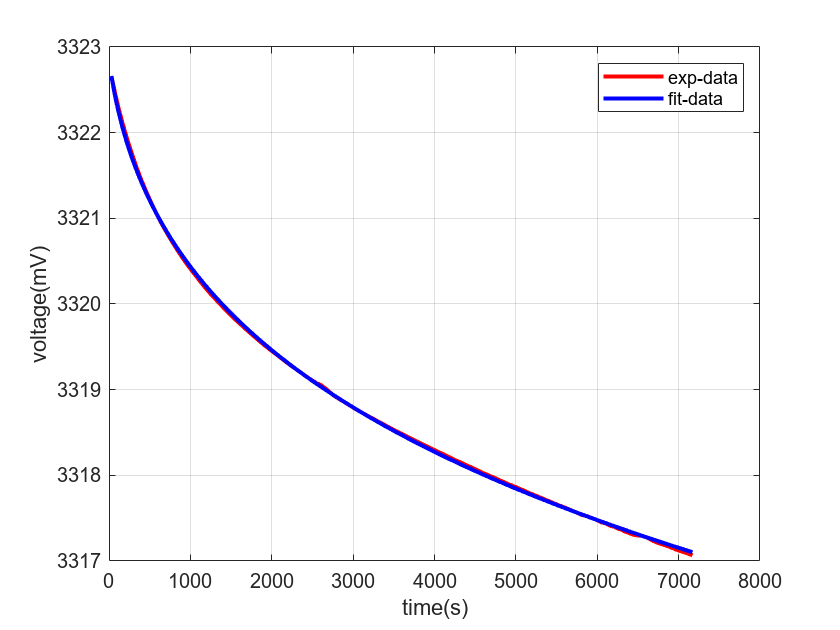

% result
[result6.RMSE,result6.Chi_2,result6.U_diff]=plot_result(result6.x_sol,exp_data,"methode",'Relaxation-nolinear');

opt_result=['result1';'result2';'result3';'result4';'result5';'result6'];
RMSE=[result1.RMSE;result2.RMSE;result3.RMSE;result4.RMSE;result5.RMSE;result6.RMSE];
Chi_2=[result1.Chi_2;result2.Chi_2;result3.Chi_2;result4.Chi_2;result5.Chi_2;result6.Chi_2];
OCV=[result1.x_sol(end);result2.x_sol(end);result3.x_sol(end);result4.x_sol(end);result5.x_sol(end);result6.x_sol(end)];
% Voltage_exp_3h=repmat(Voltage_data(241,2)*1000,[6,1]);
% diff=OCV-Voltage_exp_3h;
% results=table(opt_result,RMSE,Chi_2,OCV,Voltage_exp_3h,diff)
results=table(opt_result,RMSE,Chi_2,OCV)

results = 6×4 table
    opt_result      RMSE      Chi_2      OCV  
    __________    ________    ______    ______

     result1      0.053066    96.027    3215.6
     result2      0.019991    98.503    3296.2
     result3      0.018963     98.58    3323.7
     result4      0.018965     98.58    3323.7
     result5      0.019378    98.549    3245.5
     result6      0.018325    98.628    3263.3
